## Computational Project 

Instruction for runing the code: please import the monthlyadjustedprices.csv and monthinclude1011.csv, and the code should be able to run properly.

Load Monthly Adjusted Price

% Import data
% data from Dec 30 2004 to Sep 30 2008
monthlyadjustedprices;
data = monthlyadjustedprices;

% data from Dec 30 2004 to Nov 30 2008
monthinclude1011;

Sample Mean, Sample Variance 

% Number of months
Months = height(data);

% data from Dec 30 2004 to Sep 30 2008
data_array = table2array(monthlyadjustedprices(:, 2:end));

% compute mean, variance 
for i = 1:20
    return_g = 1;
     for j = 1:Months-1
        return_data(j,i) = data_array((j+1), i) / data_array(j, i) - 1;
        return_g = return_g * (1+return_data(j,i));
     end
     arithmetic_return(i) = mean(return_data(:,i));
     geometic_return(i) = return_g^(1/(Months-1)) - 1;
     stdev(i) = std(return_data(:,i));
end

% sample mean
geometic_return

geometic_return =    -0.0212    0.0060    0.0032    0.0167    0.0075    0.0086    0.0041   -0.0152    0.0071    0.0069    0.0284    0.0049   -0.0048    0.0039    0.0108    0.0185    0.0038    0.0068   -0.0005   -0.0023


%% sample variance
stdev.^2

ans =     0.0147    0.0043    0.0020    0.0026    0.0012    0.0013    0.0020    0.0064    0.0053    0.0058    0.0166    0.0033    0.0033    0.0010    0.0037    0.0100    0.0015    0.0034    0.0028    0.0074


%% sample covariance
cov(return_data)

ans =     0.0147    0.0015    0.0011    0.0022    0.0007   -0.0004    0.0017    0.0046    0.0020    0.0036    0.0016    0.0021    0.0013    0.0003    0.0022    0.0008    0.0011    0.0012    0.0018   -0.0002
    0.0015    0.0043    0.0009    0.0013    0.0005   -0.0001   -0.0002    0.0003   -0.0008   -0.0002    0.0037    0.0010    0.0012   -0.0003    0.0017    0.0028    0.0001    0.0019    0.0016    0.0014
    0.0011    0.0009    0.0020    0.0009    0.0005    0.0003    0.0002    0.0005   -0.0005   -0.0004    0.0014    0.0009    0.0002    0.0003    0.0002    0.0007    0.0003    0.0008    0.0007   -0.0010
    0.0022    0.0013    0.0009    0.0026    0.0010    0.0006    0.0002    0.0011    0.0003    0.0009    0.0041    0.0014    0.0006    0.0005    0.0013    0.0015    0.0008    0.0011    0.0011    0.0001
    0.0007    0.0005    0.0005    0.0010    0.0012    0.0007    0.0000    0.0006    0.0003    0.0007    0.0012    0.0005    0.0004    0.0005    0.0006    0.0004    0.0004    0.0008    0.0006

Risk-free rate, market capitalization, lambda

% calculate risk-free rate
risk_free = (4.15+4.22+4.42+4.76+3.74)/5/100/12;
risk_free

risk_free = 0.0035

% Reference: https://www.multpl.com/10-year-treasury-rate/table/by-year

% calculate market capitalization based on price and volume 
x_F = 3.47*1435125400;
x_CAT = 40.46*193168200;
x_DIS = 26.04*335173700;
x_MCD = 41.35*235712800;
x_KO = 17.32*605888800;
x_PEP = 47.19*189218100; 
x_WMT = 43.76*560153900;
x_C = 170.82*318584110;
x_WFC = 26.23*1440024400;
x_JPM = 33.25*1386597500;
x_AAPL = 3.47*24067562400;
x_IBM = 71.74*228458639;
x_PFE = 10.28*1221139419;
x_JNJ = 46.11*367504200;
x_XOM = 46.65*770778000;
x_MRO = 18.00*316680804;
x_ED = 24.14*64688000;
x_T = 7.34*937305011;
x_VZ = 15.48*456388017;
x_NEM = 30.01*236282800;

% calculate lambda
for i = 1:20
     for j = 1:Months-1
        return_data(j,i) = data_array((j+1), i) / data_array(j, i) - 1;
        excess_return = return_data - risk_free;
        mu_i_t = mean(excess_return);
        Q = cov(excess_return);
        mkt_cap = [x_F x_CAT x_DIS x_MCD x_KO x_PEP x_WMT x_C x_WFC x_JPM x_AAPL x_IBM x_PFE x_JNJ x_XOM x_MRO x_ED x_T x_VZ x_NEM];
        x_mkt = (mkt_cap/sum(mkt_cap))';
        x_mkt_t = x_mkt';
        lambda=((mu_i_t*x_mkt)-risk_free)/(x_mkt_t*Q*x_mkt);
     end
end
lambda

lambda = 2.2228

### a) Oct 2008

Mean-variance optimization (MVO)

% covariance matrix and mean return
Q = cov(return_data);
mu_i = arithmetic_return;

% MVO
f = -mu_i; 
H = Q;
Aeq = ones(1,20); 
beq = 1;
ub = ones(20,1) * inf; 
lb = -ones(20,1) * inf;

[x, fval, exitflag] = quadprog(2*lambda*H, f,[], [], Aeq, beq, lb, ub);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


if exitflag == 1
    weight_a_1(:,1) = x;
    value_a_1= fval;
else
    weight_a_1(:,1) = zeros(20,1);
    value_a_1 = 0;
end
% Reference: https://www.mathworks.com/help/optim/ug/quadprog.html

% weight of MVO
weight_a_1

weight_a_1 =    -0.0811
   -0.1271
    1.0911
    1.7006
   -1.5161
    1.0482
   -0.0695
   -2.3426
    2.8925
    0.6419


% Oct 2008 realized return
Months_1 = height(monthinclude1011);
data_array = table2array(monthinclude1011(:, 2:end));
for i = 1:20
    return_g_1 = 1;
     for j = 1:Months_1-2
        return_data_1(j,i) = data_array((j+1), i) / data_array(j, i) - 1;
        return_g_1 = return_g_1 * (1+return_data_1(j,i));
     end
     arithmetic_return_1(i) = mean(return_data_1(:,i));
     geometic_return_1(i) = return_g_1^(1/(Months_1-2)) - 1;
     stdev_1(i) = std(return_data_1(:,i));     
end


MVO portfolio return Oct 2008

return_1 = return_data_1(46,:)*weight_a_1

return_1 = 0.4352

MVO Variance & Standard deviation Oct 2008

Q_1 = cov(return_data_1)

Q_1 =     0.0213    0.0059    0.0030    0.0031    0.0028    0.0022    0.0026    0.0084    0.0032    0.0050    0.0026    0.0047    0.0017    0.0018    0.0029    0.0044    0.0010    0.0016    0.0025    0.0037
    0.0059    0.0070    0.0021    0.0018    0.0019    0.0015    0.0004    0.0028   -0.0000    0.0007    0.0043    0.0026    0.0014    0.0007    0.0022    0.0050    0.0001    0.0021    0.0021    0.0039
    0.0030    0.0021    0.0025    0.0012    0.0011    0.0011    0.0004    0.0016   -0.0001    0.0000    0.0017    0.0017    0.0003    0.0007    0.0004    0.0017    0.0002    0.0009    0.0009    0.0001
    0.0031    0.0018    0.0012    0.0027    0.0013    0.0009    0.0003    0.0017    0.0005    0.0011    0.0041    0.0017    0.0007    0.0007    0.0013    0.0019    0.0007    0.0011    0.0012    0.0006
    0.0028    0.0019    0.0011    0.0013    0.0019    0.0015    0.0003    0.0018    0.0006    0.0012    0.0015    0.0013    0.0005    0.0010    0.0008    0.0015    0.0004    0.0009    0.0008

var_1 = weight_a_1'* Q_1 * weight_a_1

var_1 = 0.0316

std_1 = (weight_a_1'* Q_1 * weight_a_1)^(1/2)

std_1 = 0.1777

MVO Sharpe Ratio Oct 2008

Sharpe_1 = (return_1 - risk_free) / std_1

Sharpe_1 = 2.4286

Robust MVO 

% covariance matrix and mean
Q = cov(return_data);
mu_i = arithmetic_return;
% theta
theta = diag(diag(Q))./Months;
theta = diag(theta);
% delta of 90% confidence interval
delta_90 = 1.645*(theta.^0.5);

% delta of 95% confidence interval
delta_95 = 1.96*(theta.^0.5);
H = Q;
f = -mu_i; 
A = -mu_i;
% expected return set by us
R = 0.26;
y = ones(20,1) * 1;
b = R - delta_90' * y;
Aeq = ones(1,20);
beq = 1;
ub = y; 
lb = -y;
[x, fval, exitflag] = quadprog(2*lambda*H, f, A, b, Aeq, beq, lb, ub);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


if exitflag == 1
    weight_a_2_90(:,1) = x;
    value_a_2_90= fval;
else
    weight_a_2_90(:,1) = zeros(20,1);
    value_a_2_90 = 0;
end

%% weight of robust MVO with 90% confidence interval
weight_a_2_90

weight_a_2_90 =    -0.4086
   -0.1716
    0.4939
    1.0000
   -0.7602
    1.0000
    0.6816
   -1.0000
    1.0000
    0.9797


Robust MVO with 90% confidence interval portfolio return Oct 2008

return_2_90 = return_data_1(46,:) * weight_a_2_90

return_2_90 = 0.2719

Robust MVO with 90% confidence interval variance and standard deviation Oct 2008

var_2_90 = weight_a_2_90'* Q_1 * weight_a_2_90

var_2_90 = 0.0176

std_2_90 = (weight_a_2_90'* Q_1 * weight_a_2_90)^(1/2)

std_2_90 = 0.1326

Robust MVO with 90% confidence interval Sharpe ratio Oct 2008

Sharpe_2_90 = (return_2_90 - risk_free) / std_2_90

Sharpe_2_90 = 2.0240

H = Q;
f = -mu_i; 
A = -mu_i;
% expected return set by us
R = 0.26;
y = ones(20,1) * 1;
b = R - delta_95' * y;
Aeq = ones(1,20);
beq = 1;
ub = y; 
lb = -y;
[x, fval, exitflag] = quadprog(2*lambda*H, f, A, b, Aeq, beq, lb, ub);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


if exitflag == 1
    weight_a_2_95(:,1) = x;
    value_a_2_95= fval;
else
    weight_a_2_95(:,1) = zeros(20,1);
    value_a_2_95 = 0;
end

%% weight of robust MVO with 95% confidence interval
weight_a_2_95

weight_a_2_95 =    -0.5765
   -0.2481
    0.2743
    1.0000
   -0.4690
    1.0000
    1.0000
   -1.0000
    1.0000
    1.0000


Robust MVO with 95% confidence interval portfolio return Oct 2008

return_2_95 = return_data_1(46,:) * weight_a_2_95

return_2_95 = 0.3779

Robust MVO with 95% confidence interval variance and standard deviation Oct 2008

var_2_95 = weight_a_2_95'* Q_1 * weight_a_2_95

var_2_95 = 0.0263

std_2_95 = (weight_a_2_95'* Q_1 * weight_a_2_95)^(1/2)

std_2_95 = 0.1623

Robust MVO with 95% confidence Sharpe Ratio Oct 2008

Sharpe_2_95 = (return_2_95 - risk_free) / std_2_95

Sharpe_2_95 = 2.3061

Risk Parity optimization with no short selling

W = zeros(20,1);
Sigma = Q;
f = @(W)var(W.*(Sigma*W))*10^14;
% Reference: https://www.mathworks.com/matlabcentral/answers/278745-risk-parity-equal-risk-contribution-optimization

% weight of risk parity portfolio
weight_a_3 = fmincon(f, W, [], [], ones(1,length(W)),1)


Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3.000000e+03.



weight_a_3 =     0.0055
    0.0108
    0.0220
    0.0096
    0.0186
    0.0308
    0.0481
    0.0083
    0.0172
    0.0097


Risk Parity portfolio return Oct 2008

return_3 = return_data_1(46,:) * weight_a_3

return_3 = -0.0484

Risk Parity variance and standard deviation Oct 2008

var_3 = weight_a_3'* Q_1 * weight_a_3

var_3 = 1.0659e-04

std_3 = (weight_a_3'* Q_1 * weight_a_3)^(1/2)

std_3 = 0.0103

Risk Parity Sharpe ratio Oct 2008

Sharpe_3 = (return_3 - risk_free) / std_3

Sharpe_3 = -5.0307

Market Capitalization

Market Capitalization portfolio return Oct 2008

return_4 = return_data_1(46,:) * x_mkt

return_4 = -0.1360

Market Capitalization variance and standard deviation Oct 2008

var_4 = x_mkt_t * Q_1 * x_mkt

var_4 = 0.0023

std_4 = (x_mkt_t * Q_1 * x_mkt)^(1/2)

std_4 = 0.0476

Market Capitalization Sharpe ratio Oct 2008

Sharpe_4 = (return_4 - risk_free) / std_4

Sharpe_4 = -2.9303

### b) Nov 2008

Mean-variance optimization

% realized return of Nov 2008
Months_1 = height(monthinclude1011);
data_array = table2array(monthinclude1011(:, 2:end));
for i = 1:20
    return_g_2 = 1;
     for j = 1:Months_1-1
        return_data_2(j,i) = data_array((j+1), i) / data_array(j, i) - 1;
        return_g_2 = return_g_2 * (1+return_data_2(j,i));
     end
     arithmetic_return_2(i) = mean(return_data_2(:,i));
     geometic_return_2(i) = return_g_2^(1/(Months_1-1)) - 1;
     stdev_2(i) = std(return_data_2(:,i));     
end

MVO portfolio return Nov 2008

return_1_b = return_data_2(47,:)*weight_a_1

return_1_b = 0.4435

MVO variance and standard deviation Nov 2008

% updated covariance matrix 
Q_2 = cov(return_data_2)

Q_2 =     0.0222    0.0062    0.0022    0.0031    0.0031    0.0021    0.0025    0.0062    0.0023    0.0036    0.0016    0.0039    0.0014    0.0015    0.0033    0.0037    0.0007    0.0019    0.0030    0.0052
    0.0062    0.0070    0.0018    0.0018    0.0019    0.0015    0.0004    0.0022   -0.0002    0.0003    0.0039    0.0024    0.0013    0.0006    0.0022    0.0048   -0.0000    0.0021    0.0022    0.0043
    0.0022    0.0018    0.0028    0.0011    0.0009    0.0011    0.0004    0.0026    0.0003    0.0007    0.0021    0.0020    0.0004    0.0008    0.0002    0.0019    0.0004    0.0007    0.0006   -0.0007
    0.0031    0.0018    0.0011    0.0026    0.0013    0.0009    0.0003    0.0016    0.0004    0.0010    0.0040    0.0017    0.0007    0.0007    0.0013    0.0019    0.0007    0.0011    0.0012    0.0006
    0.0031    0.0019    0.0009    0.0013    0.0019    0.0014    0.0003    0.0012    0.0004    0.0008    0.0012    0.0011    0.0004    0.0009    0.0009    0.0013    0.0003    0.0009    0.0010

var_1_b = weight_a_1'* Q_2 * weight_a_1

var_1_b = 0.0328

std_1_b = (weight_a_1'* Q_2 * weight_a_1)^(1/2)

std_1_b = 0.1810

MVO Sharpe ratio Nov 2008

Sharpe_1_b = (return_1_b - risk_free) / std_1_b

Sharpe_1_b = 2.4303

Robust MVO

Robust MVO with 90% confidence interval portfolio return Nov 2008 

return_2_90_b = return_data_2(47,:) * weight_a_2_90

return_2_90_b = -0.1320

Robust MVO with 90% confidence interval variance and standard deviation Nov 2008

var_2_90_b = weight_a_2_90'* Q_2 * weight_a_2_90

var_2_90_b = 0.0184

std_2_90_b = (weight_a_2_90'* Q_2 * weight_a_2_90)^(1/2)

std_2_90_b = 0.1355

Robust MVO with 90% confidence interval Sharpe ratio Nov 2008

Sharpe_2_90_b = (return_2_90_b - risk_free) / std_2_90_b

Sharpe_2_90_b = -1.0002

Robust MVO with 95% confidence interval portfolio return Nov 2008

return_2_95_b = return_data_2(47,:) * weight_a_2_95

return_2_95_b = -0.2185

Robust MVO with 95% confidence interval variance and standard deviation Nov 2008

var_2_95_b = weight_a_2_95'* Q_2 * weight_a_2_95

var_2_95_b = 0.0282

std_2_95_b = (weight_a_2_95'* Q_2 * weight_a_2_95)^(1/2)

std_2_95_b = 0.1680

Robust MVO with 95% confidence interval Sharpe ratio Nov 2008

Sharpe_2_95 = (return_2_95_b - risk_free) / std_2_95_b

Sharpe_2_95 = -1.3216

Risk Parity optimization with no short selling.

Risk Parity portfolio return Nov 2008

return_3_b = return_data_2(47,:) * weight_a_3

return_3_b = -0.0028

Risk Parity variance and standard deviation Nov 2008

var_3_b = weight_a_3'* Q_2 * weight_a_3

var_3_b = 1.0458e-04

std_3_b = (weight_a_3'* Q_2 * weight_a_3)^(1/2)

std_3_b = 0.0102

Risk Parity Sharpe ratio Nov 2008

Sharpe_3 = (return_3_b - risk_free) / std_3_b

Sharpe_3 = -0.6193

Market Capitalization

Market Capitalization portfolio return Nov 2008

return_4_b = return_data_2(47,:) * x_mkt

return_4_b = -0.1108

Market Capitalization variance and standard deviation Nov 2008

var_4_b = x_mkt_t * Q_2 * x_mkt

var_4_b = 0.0025

std_4_b = (x_mkt_t * Q_2 * x_mkt)^(1/2)

std_4_b = 0.0502

Market Capitalization Sharpe ratio Nov 2008

Sharpe_4_b = (return_4_b - risk_free) / std_4_b

Sharpe_4_b = -2.2780

### c) Efficient Frontiers

% estimate, actual and true MVO
% covariance matrix
Q = cov(return_data);
% include October
Q_1 = cov(return_data_1);

mu_i = arithmetic_return;
f = -mu_i; 
f_1 = -arithmetic_return_1; 
H = Q;
H_1 = Q_1;

% lambda range we selected
lambda_1 =[0.5:.5:50];

for a=1:length(lambda_1)
    Aeq = ones(1,20); 
    beq = 1;
    ub = ones(20,1) * inf; 
    lb = -ones(20,1) * inf;
    [x, fval, exitflag] = quadprog(2*lambda_1(a)*H, f,[], [], Aeq, beq, lb, ub);
    
    if exitflag == 1
        weight_b_1(:,1) = x;
        value_b_1= fval;
    else
        weight_b_1(:,1) = zeros(20,1);
        value_b_1 = 0;
    end
    % estimated
    std_devi_est(a,1) = ((weight_b_1') * Q_1 * weight_b_1)^.5
    goal_est(a,1) = mu_i * weight_b_1
    % actual
    std_devi_actual(a,1) = ((weight_b_1') * Q_1 * weight_b_1)^.5
    goal_actual(a,1) = return_data_1(46,:) * weight_b_1
    
    [x, fval, exitflag] = quadprog(2*lambda_1(a)*H_1, f_1,[], [], Aeq, beq, lb, ub);
    
    if exitflag == 1
        weight_c_1(:,1) = x;
        value_c_1= fval;
    else
        weight_c_1(:,1) = zeros(20,1);
        value_c_1 = 0;
    end
    % true
    std_devi_true(a,1) = ((weight_c_1') * Q_1 * weight_c_1)^.5
    goal_true(a,1) = return_data_1(46,:) * weight_c_1

end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 0.8076

goal_est = 0.6020

std_devi_actual = 0.8076

goal_actual = 2.3823


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 0.7918

goal_true = 1.7721


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est =     0.8076
    0.4009


goal_est =     0.6020
    0.3038


std_devi_actual =     0.8076
    0.4009


goal_actual =     2.3823
    1.1262



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true =     0.7918
    0.3962


goal_true =     1.7721
    0.8759



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est =     0.8076
    0.4009
    0.2655


goal_est =     0.6020
    0.3038
    0.2044


std_devi_actual =     0.8076
    0.4009
    0.2655


goal_actual =     2.3823
    1.1262
    0.7075



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true =     0.7918
    0.3962
    0.2644


goal_true =     1.7721
    0.8759
    0.5772



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est =     0.8076
    0.4009
    0.2655
    0.1980


goal_est =     0.6020
    0.3038
    0.2044
    0.1547


std_devi_actual =     0.8076
    0.4009
    0.2655
    0.1980


goal_actual =     2.3823
    1.1262
    0.7075
    0.4981



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true =     0.7918
    0.3962
    0.2644
    0.1986


goal_true =     1.7721
    0.8759
    0.5772
    0.4278



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est =     0.8076
    0.4009
    0.2655
    0.1980
    0.1576


goal_est =     0.6020
    0.3038
    0.2044
    0.1547
    0.1249


std_devi_actual =     0.8076
    0.4009
    0.2655
    0.1980
    0.1576


goal_actual =     2.3823
    1.1262
    0.7075
    0.4981
    0.3725



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true =     0.7918
    0.3962
    0.2644
    0.1986
    0.1591


goal_true =     1.7721
    0.8759
    0.5772
    0.4278
    0.3382



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est =     0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308


goal_est =     0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050


std_devi_actual =     0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308


goal_actual =     2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true =     0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329


goal_true =     1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est =     0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118


goal_est =     0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908


std_devi_actual =     0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118


goal_actual =     2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true =     0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142


goal_true =     1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est =     0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976


goal_est =     0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802


std_devi_actual =     0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976


goal_actual =     2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true =     0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003


goal_true = 8×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 9×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866


goal_est = 9×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719


std_devi_actual = 9×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866


goal_actual = 9×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 9×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894


goal_true = 9×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 10×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 10×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 10×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 10×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 10×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 10×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 11×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 11×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 11×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 11×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 11×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 11×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 12×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 12×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 12×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 12×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 12×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 12×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 13×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 13×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 13×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 13×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 13×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 13×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 14×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 14×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 14×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 14×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 14×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 14×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 15×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 15×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 15×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 15×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 15×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 15×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 16×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 16×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 16×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 16×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 16×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 16×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 17×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 17×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 17×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 17×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 17×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 17×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 18×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 18×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 18×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 18×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 18×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 18×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 19×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 19×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 19×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 19×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 19×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 19×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 20×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 20×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 20×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 20×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 20×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 20×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 21×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 21×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 21×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 21×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 21×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 21×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 22×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 22×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 22×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 22×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 22×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 22×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 23×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 23×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 23×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 23×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 23×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 23×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 24×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 24×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 24×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 24×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 24×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 24×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 25×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 25×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 25×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 25×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 25×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 25×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 26×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 26×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 26×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 26×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 26×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 26×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 27×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 27×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 27×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 27×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 27×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 27×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 28×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 28×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 28×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 28×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 28×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 28×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 29×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 29×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 29×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 29×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 29×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 29×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 30×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 30×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 30×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 30×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 30×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 30×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 31×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 31×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 31×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 31×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 31×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 31×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 32×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 32×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 32×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 32×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 32×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 32×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 33×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 33×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 33×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 33×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 33×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 33×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 34×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 34×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 34×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 34×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 34×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 34×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 35×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 35×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 35×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 35×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 35×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 35×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 36×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 36×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 36×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 36×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 36×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 36×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 37×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 37×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 37×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 37×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 37×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 37×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 38×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 38×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 38×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 38×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 38×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 38×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 39×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 39×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 39×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 39×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 39×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 39×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 40×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 40×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 40×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 40×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 40×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 40×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 41×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 41×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 41×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 41×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 41×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 41×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 42×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 42×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 42×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 42×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 42×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 42×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 43×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 43×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 43×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 43×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 43×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 43×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 44×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 44×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 44×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 44×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 44×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 44×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 45×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 45×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 45×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 45×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 45×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 45×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 46×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 46×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 46×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 46×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 46×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 46×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 47×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 47×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 47×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 47×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 47×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 47×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 48×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 48×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 48×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 48×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 48×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 48×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 49×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 49×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 49×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 49×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 49×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 49×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 50×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 50×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 50×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 50×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 50×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 50×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 51×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 51×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 51×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 51×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 51×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 51×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 52×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 52×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 52×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 52×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 52×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 52×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 53×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 53×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 53×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 53×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 53×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 53×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 54×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 54×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 54×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 54×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 54×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 54×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 55×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 55×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 55×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 55×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 55×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 55×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 56×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 56×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 56×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 56×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 56×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 56×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 57×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 57×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 57×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 57×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 57×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 57×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 58×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 58×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 58×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 58×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 58×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 58×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 59×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 59×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 59×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 59×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 59×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 59×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 60×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 60×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 60×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 60×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 60×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 60×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 61×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 61×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 61×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 61×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 61×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 61×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 62×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 62×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 62×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 62×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 62×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 62×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 63×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 63×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 63×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 63×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 63×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 63×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 64×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 64×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 64×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 64×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 64×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 64×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 65×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 65×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 65×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 65×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 65×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 65×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 66×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 66×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 66×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 66×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 66×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 66×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 67×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 67×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 67×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 67×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 67×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 67×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 68×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 68×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 68×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 68×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 68×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 68×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 69×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 69×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 69×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 69×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 69×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 69×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 70×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 70×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 70×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 70×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 70×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 70×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 71×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 71×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 71×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 71×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 71×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 71×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 72×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 72×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 72×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 72×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 72×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 72×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 73×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 73×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 73×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 73×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 73×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 73×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 74×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 74×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 74×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 74×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 74×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 74×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 75×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 75×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 75×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 75×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 75×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 75×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 76×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 76×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 76×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 76×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 76×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 76×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 77×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 77×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 77×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 77×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 77×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 77×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 78×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 78×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 78×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 78×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 78×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 78×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 79×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 79×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 79×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 79×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 79×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 79×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 80×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 80×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 80×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 80×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 80×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 80×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 81×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 81×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 81×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 81×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 81×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 81×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 82×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 82×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 82×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 82×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 82×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 82×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 83×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 83×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 83×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 83×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 83×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 83×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 84×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 84×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 84×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 84×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 84×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 84×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 85×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 85×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 85×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 85×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 85×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 85×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 86×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 86×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 86×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 86×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 86×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 86×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 87×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 87×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 87×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 87×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 87×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 87×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 88×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 88×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 88×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 88×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 88×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 88×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 89×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 89×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 89×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 89×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 89×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 89×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 90×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 90×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 90×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 90×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 90×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 90×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 91×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 91×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 91×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 91×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 91×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 91×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 92×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 92×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 92×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 92×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 92×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 92×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 93×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 93×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 93×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 93×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 93×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 93×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 94×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 94×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 94×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 94×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 94×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 94×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 95×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 95×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 95×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 95×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 95×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 95×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 96×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 96×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 96×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 96×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 96×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 96×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 97×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 97×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 97×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 97×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 97×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 97×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 98×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 98×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 98×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 98×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 98×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 98×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 99×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 99×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 99×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 99×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 99×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 99×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_est = 100×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_est = 100×1
    0.6020
    0.3038
    0.2044
    0.1547
    0.1249
    0.1050
    0.0908
    0.0802
    0.0719
    0.0653


std_devi_actual = 100×1
    0.8076
    0.4009
    0.2655
    0.1980
    0.1576
    0.1308
    0.1118
    0.0976
    0.0866
    0.0780


goal_actual = 100×1
    2.3823
    1.1262
    0.7075
    0.4981
    0.3725
    0.2888
    0.2289
    0.1841
    0.1492
    0.1213



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_true = 100×1
    0.7918
    0.3962
    0.2644
    0.1986
    0.1591
    0.1329
    0.1142
    0.1003
    0.0894
    0.0808


goal_true = 100×1
    1.7721
    0.8759
    0.5772
    0.4278
    0.3382
    0.2785
    0.2358
    0.2038
    0.1789
    0.1590


% estimated and actual robust MVO
% covariance matrix
Q = cov(return_data);
% include October
Q_1 = cov(return_data_1);

mu_i = arithmetic_return;
theta = diag(diag(Q))./Months;
theta = diag(theta);
delta_90 = 1.645*(theta.^0.5);
delta_95 = 1.96*(theta.^0.5);

H = Q;
f = -mu_i; 
A = -mu_i;
% expected return set by us
R = 0.26; 
y = ones(20,1) * 1;
Aeq = ones(1,20);
beq = 1;
ub = y; 
lb = -y;

for a=1:length(lambda_1)
    b_1 = R - delta_90' * y;
    [x, fval, exitflag] = quadprog(2*lambda_1(a)*H, f, A, b_1, Aeq, beq, lb, ub);
    
    if exitflag == 1
        weight_d_1(:,1) = x;
        value_d_1= fval;
    else
        weight_d_1(:,1) = zeros(20,1);
        value_d_1 = 0;
    end
    % estimated (90% CI) 
    std_devi_estr90(a,1) = ((weight_d_1') * Q * weight_d_1)^.5
    goal_estr90(a,1) = mu_i * weight_d_1
    % actual (90% CI)
    std_devi_actualr90(a,1) = ((weight_d_1') * Q_1 * weight_d_1)^.5
    goal_actualr90(a,1) = return_data_1(46,:) * weight_d_1
    
    b_2 = R - delta_95' * y;
    [x, fval, exitflag] = quadprog(2*lambda_1(a)*H, f, A, b_2, Aeq, beq, lb, ub);
    
    if exitflag == 1
        weight_e_1(:,1) = x;
        value_e_1= fval;
    else
        weight_e_1(:,1) = zeros(20,1);
        value_e_1 = 0;
    end
    % estimated (95% CI)
    std_devi_estr95(a,1) = ((weight_e_1') * Q * weight_e_1)^.5
    goal_estr95(a,1) = mu_i * weight_e_1
    % actual (95% CI)
    std_devi_actualr95(a,1) = ((weight_e_1') * Q_1 * weight_e_1)^.5
    goal_actualr95(a,1) = return_data_1(46,:) * weight_e_1

end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 0.2369

goal_estr90 = 0.1477

std_devi_actualr90 = 0.2428

goal_actualr90 = 0.5796


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 0.2369

goal_estr95 = 0.1477

std_devi_actualr95 = 0.2428

goal_actualr95 = 0.5796


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 2×1
    0.2369
    0.2103


goal_estr90 = 2×1
    0.1477
    0.1380


std_devi_actualr90 = 2×1
    0.2428
    0.2159


goal_actualr90 = 2×1
    0.5796
    0.5331



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 2×1
    0.2369
    0.2103


goal_estr95 = 2×1
    0.1477
    0.1380


std_devi_actualr95 = 2×1
    0.2428
    0.2159


goal_actualr95 = 2×1
    0.5796
    0.5331



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 3×1
    0.2369
    0.2103
    0.1655


goal_estr90 = 3×1
    0.1477
    0.1380
    0.1178


std_devi_actualr90 = 3×1
    0.2428
    0.2159
    0.1689


goal_actualr90 = 3×1
    0.5796
    0.5331
    0.4014



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 3×1
    0.2369
    0.2103
    0.1655


goal_estr95 = 3×1
    0.1477
    0.1380
    0.1178


std_devi_actualr95 = 3×1
    0.2428
    0.2159
    0.1689


goal_actualr95 = 3×1
    0.5796
    0.5331
    0.4014



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 4×1
    0.2369
    0.2103
    0.1655
    0.1400


goal_estr90 = 4×1
    0.1477
    0.1380
    0.1178
    0.1044


std_devi_actualr90 = 4×1
    0.2428
    0.2159
    0.1689
    0.1417


goal_actualr90 = 4×1
    0.5796
    0.5331
    0.4014
    0.3085



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 4×1
    0.2369
    0.2103
    0.1655
    0.1594


goal_estr95 = 4×1
    0.1477
    0.1380
    0.1178
    0.1147


std_devi_actualr95 = 4×1
    0.2428
    0.2159
    0.1689
    0.1623


goal_actualr95 = 4×1
    0.5796
    0.5331
    0.4014
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 5×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217


goal_estr90 = 5×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936


std_devi_actualr90 = 5×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220


goal_actualr90 = 5×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 5×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594


goal_estr95 = 5×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147


std_devi_actualr95 = 5×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623


goal_actualr95 = 5×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 6×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071


goal_estr90 = 6×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845


std_devi_actualr90 = 6×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071


goal_actualr90 = 6×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 6×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594


goal_estr95 = 6×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 6×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623


goal_actualr95 = 6×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 7×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966


goal_estr90 = 7×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776


std_devi_actualr90 = 7×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967


goal_actualr90 = 7×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 7×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 7×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 7×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 7×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 8×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882


goal_estr90 = 8×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718


std_devi_actualr90 = 8×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883


goal_actualr90 = 8×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 8×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 8×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 8×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 8×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 9×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811


goal_estr90 = 9×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667


std_devi_actualr90 = 9×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811


goal_actualr90 = 9×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 9×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 9×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 9×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 9×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 10×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 10×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 10×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 10×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 10×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 10×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 10×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 10×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 11×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 11×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 11×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 11×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 11×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 11×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 11×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 11×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 12×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 12×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 12×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 12×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 12×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 12×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 12×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 12×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 13×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 13×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 13×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 13×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 13×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 13×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 13×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 13×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 14×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 14×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 14×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 14×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 14×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 14×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 14×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 14×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 15×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 15×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 15×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 15×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 15×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 15×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 15×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 15×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 16×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 16×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 16×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 16×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 16×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 16×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 16×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 16×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 17×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 17×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 17×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 17×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 17×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 17×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 17×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 17×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 18×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 18×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 18×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 18×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 18×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 18×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 18×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 18×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 19×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 19×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 19×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 19×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 19×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 19×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 19×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 19×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 20×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 20×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 20×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 20×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 20×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 20×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 20×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 20×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 21×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 21×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 21×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 21×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 21×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 21×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 21×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 21×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 22×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 22×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 22×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 22×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 22×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 22×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 22×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 22×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 23×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 23×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 23×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 23×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 23×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 23×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 23×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 23×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 24×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 24×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 24×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 24×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 24×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 24×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 24×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 24×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 25×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 25×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 25×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 25×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 25×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 25×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 25×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 25×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 26×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 26×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 26×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 26×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 26×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 26×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 26×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 26×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 27×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 27×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 27×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 27×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 27×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 27×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 27×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 27×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 28×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 28×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 28×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 28×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 28×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 28×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 28×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 28×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 29×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 29×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 29×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 29×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 29×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 29×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 29×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 29×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 30×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 30×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 30×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 30×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 30×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 30×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 30×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 30×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 31×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 31×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 31×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 31×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 31×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 31×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 31×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 31×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 32×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 32×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 32×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 32×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 32×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 32×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 32×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 32×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 33×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 33×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 33×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 33×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 33×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 33×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 33×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 33×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 34×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 34×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 34×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 34×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 34×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 34×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 34×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 34×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 35×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 35×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 35×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 35×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 35×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 35×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 35×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 35×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 36×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 36×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 36×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 36×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 36×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 36×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 36×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 36×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 37×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 37×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 37×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 37×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 37×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 37×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 37×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 37×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 38×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 38×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 38×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 38×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 38×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 38×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 38×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 38×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 39×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 39×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 39×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 39×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 39×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 39×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 39×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 39×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 40×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 40×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 40×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 40×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 40×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 40×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 40×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 40×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 41×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 41×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 41×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 41×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 41×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 41×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 41×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 41×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 42×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 42×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 42×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 42×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 42×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 42×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 42×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 42×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 43×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 43×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 43×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 43×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 43×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 43×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 43×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 43×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 44×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 44×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 44×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 44×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 44×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 44×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 44×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 44×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 45×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 45×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 45×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 45×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 45×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 45×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 45×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 45×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 46×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 46×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 46×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 46×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 46×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 46×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 46×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 46×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 47×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 47×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 47×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 47×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 47×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 47×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 47×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 47×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 48×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 48×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 48×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 48×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 48×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 48×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 48×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 48×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 49×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 49×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 49×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 49×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 49×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 49×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 49×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 49×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 50×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 50×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 50×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 50×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 50×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 50×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 50×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 50×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 51×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 51×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 51×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 51×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 51×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 51×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 51×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 51×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 52×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 52×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 52×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 52×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 52×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 52×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 52×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 52×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 53×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 53×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 53×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 53×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 53×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 53×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 53×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 53×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 54×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 54×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 54×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 54×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 54×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 54×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 54×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 54×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 55×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 55×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 55×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 55×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 55×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 55×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 55×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 55×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 56×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 56×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 56×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 56×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 56×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 56×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 56×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 56×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 57×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 57×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 57×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 57×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 57×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 57×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 57×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 57×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 58×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 58×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 58×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 58×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 58×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 58×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 58×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 58×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 59×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 59×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 59×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 59×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 59×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 59×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 59×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 59×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 60×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 60×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 60×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 60×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 60×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 60×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 60×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 60×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 61×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 61×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 61×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 61×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 61×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 61×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 61×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 61×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 62×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 62×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 62×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 62×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 62×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 62×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 62×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 62×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 63×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 63×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 63×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 63×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 63×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 63×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 63×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 63×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 64×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 64×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 64×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 64×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 64×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 64×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 64×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 64×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 65×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 65×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 65×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 65×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 65×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 65×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 65×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 65×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 66×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 66×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 66×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 66×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 66×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 66×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 66×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 66×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 67×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 67×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 67×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 67×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 67×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 67×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 67×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 67×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 68×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 68×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 68×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 68×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 68×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 68×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 68×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 68×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 69×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 69×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 69×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 69×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 69×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 69×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 69×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 69×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 70×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 70×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 70×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 70×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 70×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 70×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 70×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 70×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 71×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 71×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 71×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 71×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 71×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 71×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 71×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 71×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 72×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 72×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 72×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 72×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 72×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 72×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 72×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 72×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 73×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 73×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 73×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 73×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 73×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 73×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 73×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 73×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 74×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 74×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 74×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 74×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 74×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 74×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 74×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 74×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 75×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 75×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 75×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 75×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 75×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 75×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 75×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 75×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 76×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 76×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 76×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 76×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 76×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 76×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 76×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 76×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 77×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 77×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 77×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 77×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 77×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 77×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 77×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 77×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 78×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 78×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 78×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 78×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 78×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 78×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 78×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 78×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 79×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 79×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 79×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 79×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 79×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 79×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 79×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 79×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 80×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 80×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 80×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 80×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 80×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 80×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 80×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 80×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 81×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 81×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 81×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 81×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 81×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 81×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 81×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 81×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 82×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 82×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 82×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 82×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 82×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 82×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 82×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 82×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 83×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 83×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 83×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 83×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 83×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 83×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 83×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 83×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 84×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 84×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 84×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 84×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 84×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 84×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 84×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 84×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 85×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 85×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 85×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 85×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 85×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 85×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 85×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 85×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 86×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 86×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 86×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 86×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 86×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 86×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 86×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 86×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 87×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 87×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 87×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 87×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 87×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 87×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 87×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 87×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 88×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 88×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 88×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 88×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 88×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 88×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 88×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 88×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 89×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 89×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 89×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 89×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 89×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 89×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 89×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 89×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 90×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 90×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 90×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 90×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 90×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 90×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 90×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 90×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 91×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 91×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 91×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 91×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 91×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 91×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 91×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 91×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 92×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 92×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 92×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 92×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 92×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 92×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 92×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 92×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 93×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 93×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 93×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 93×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 93×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 93×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 93×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 93×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 94×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 94×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 94×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 94×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 94×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 94×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 94×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 94×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 95×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 95×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 95×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 95×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 95×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 95×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 95×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 95×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 96×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 96×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 96×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 96×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 96×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 96×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 96×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 96×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 97×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 97×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 97×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 97×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 97×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 97×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 97×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 97×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 98×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 98×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 98×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 98×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 98×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 98×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 98×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 98×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 99×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 99×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 99×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 99×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 99×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 99×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 99×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 99×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr90 = 100×1
    0.2369
    0.2103
    0.1655
    0.1400
    0.1217
    0.1071
    0.0966
    0.0882
    0.0811
    0.0748


goal_estr90 = 100×1
    0.1477
    0.1380
    0.1178
    0.1044
    0.0936
    0.0845
    0.0776
    0.0718
    0.0667
    0.0620


std_devi_actualr90 = 100×1
    0.2428
    0.2159
    0.1689
    0.1417
    0.1220
    0.1071
    0.0967
    0.0883
    0.0811
    0.0746


goal_actualr90 = 100×1
    0.5796
    0.5331
    0.4014
    0.3085
    0.2302
    0.1943
    0.1796
    0.1678
    0.1519
    0.1313



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


std_devi_estr95 = 100×1
    0.2369
    0.2103
    0.1655
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594
    0.1594


goal_estr95 = 100×1
    0.1477
    0.1380
    0.1178
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147
    0.1147


std_devi_actualr95 = 100×1
    0.2428
    0.2159
    0.1689
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623
    0.1623


goal_actualr95 = 100×1
    0.5796
    0.5331
    0.4014
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779
    0.3779


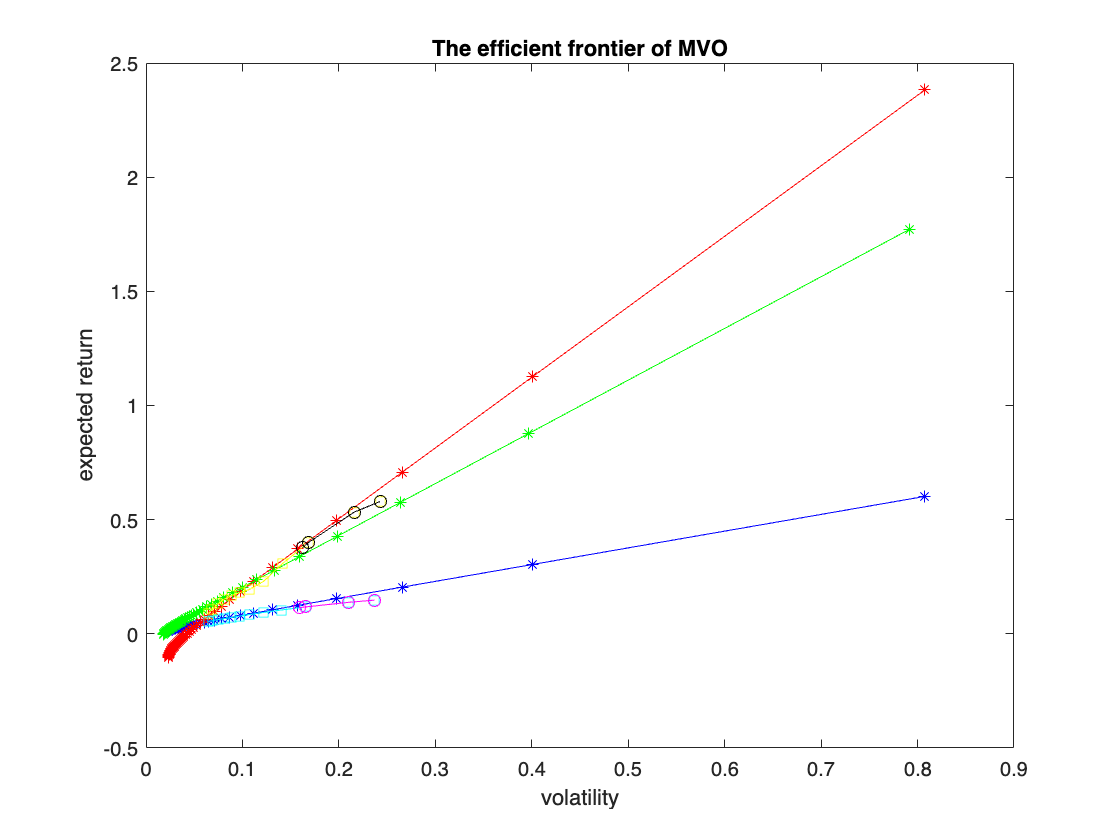

% plot efficient frontier
plot(std_devi_est, goal_est, '-k*', 'Color', 'b')
hold on
plot(std_devi_actual, goal_actual, '-k*', 'Color', 'r')
hold on
plot(std_devi_true, goal_true, '-k*', 'Color', 'g')
hold on
plot(std_devi_actualr90, goal_actualr90, '-ks', 'Color', 'y')
hold on
plot(std_devi_actualr95, goal_actualr95, '-ko', 'Color', 'k')
hold on
plot(std_devi_estr90, goal_estr90, '-ks', 'Color', 'c')
hold on
plot(std_devi_estr95, goal_estr95, '-ko', 'Color', 'm')

xlabel('volatility')
ylabel('expected return')
title('The efficient frontier of MVO')